# BIOMECH II HW3 code by Erika Muhlrad

## #1

%a) 

a_0 = [1/sqrt(2); 1/sqrt(2); 0]

a_0 =     0.7071
    0.7071
         0



%b)

a0_inner = a_0 * a_0'

a0_inner =     0.5000    0.5000         0
    0.5000    0.5000         0
         0         0         0



%c)

syms lambda1 lambda2 lambda_f
F = [lambda1 0 0;
    0 lambda2 0;
    0 0 1/(lambda1*lambda2)]

$$F = \left(\begin{array}{ccc} \lambda_{1} & 0 & 0\\ 0 & \lambda_{2} & 0\\ 0 & 0 & \frac{1}{\lambda_{1}\,\lambda_{2}} \end{array}\right)$$


%d)


lambda_f = norm(F*a_0)

$$lambda\_f = \sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}$$



a = (F*a_0)./lambda_f

$$a = \left(\begin{array}{c} \frac{\sqrt{2}\,\lambda_{1}}{2\,\sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}}\\ \frac{\sqrt{2}\,\lambda_{2}}{2\,\sqrt{\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}}}\\ 0 \end{array}\right)$$


%e)
a_inner = a * a'

$$a\_inner = \begin{array}{l} \left(\begin{array}{ccc} \frac{\lambda_{1}\,\bar{\lambda_{1}}}{\sigma_{1}} & \frac{\lambda_{1}\,\bar{\lambda_{2}}}{\sigma_{1}} & 0\\ \frac{\lambda_{2}\,\bar{\lambda_{1}}}{\sigma_{1}} & \frac{\lambda_{2}\,\bar{\lambda_{2}}}{\sigma_{1}} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(\frac{{\left|\lambda_{1}\right|}^{2}}{2}+\frac{{\left|\lambda_{2}\right|}^{2}}{2}\right) \end{array}$$




%f)
syms I1 I2 I3 I4 I5 c1 c2 c3

W = (c1*(I1-3)) + c2*(exp(c3*((I4-1)^2))-1)

$$W = c_{2}\,\left({\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}-1\right)+c_{1}\,\left(I_{1}-3\right)$$

W1 = diff(W,I1)

$$W1 = c_{1}$$

W2 = diff(W,I2)

$$W2 = 0$$

W3 = diff(W,I3)

$$W3 = 0$$

W4 = diff(W,I4)

$$W4 = c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right)$$

W5 = diff(W,I5)

$$W5 = 0$$


%g) 

S = 2*((W1 * eye(3))+ (W4 * a_0 * a_0'))

$$S = \begin{array}{l} \left(\begin{array}{ccc} 2\,c_{1}+\sigma_{1} & \sigma_{1} & 0\\ \sigma_{1} & 2\,c_{1}+\sigma_{1} & 0\\ 0 & 0 & 2\,c_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=c_{2}\,c_{3}\,{\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}}\,\left(2\,I_{4}-2\right) \end{array}$$


T = F*S*F'

$$T = \begin{array}{l} \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}}\,\sigma_{1} & c_{2}\,c_{3}\,\lambda_{1}\,\sigma_{2}\,\bar{\lambda_{2}}\,\left(2\,I_{4}-2\right) & 0\\ c_{2}\,c_{3}\,\lambda_{2}\,\sigma_{2}\,\bar{\lambda_{1}}\,\left(2\,I_{4}-2\right) & \lambda_{2}\,\bar{\lambda_{2}}\,\sigma_{1} & 0\\ 0 & 0 & \frac{2\,c_{1}}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,c_{1}+c_{2}\,c_{3}\,\sigma_{2}\,\left(2\,I_{4}-2\right)\\ \sigma_{2}={\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}} \end{array}$$


pnh = T(3,3)

$$pnh = \frac{2\,c_{1}}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}}$$

T = T - pnh*eye(3)

$$T = \begin{array}{l} \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}}\,\sigma_{1}-\frac{2\,c_{1}}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} & c_{2}\,c_{3}\,\lambda_{1}\,\sigma_{2}\,\bar{\lambda_{2}}\,\left(2\,I_{4}-2\right) & 0\\ c_{2}\,c_{3}\,\lambda_{2}\,\sigma_{2}\,\bar{\lambda_{1}}\,\left(2\,I_{4}-2\right) & \lambda_{2}\,\bar{\lambda_{2}}\,\sigma_{1}-\frac{2\,c_{1}}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} & 0\\ 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,c_{1}+c_{2}\,c_{3}\,\sigma_{2}\,\left(2\,I_{4}-2\right)\\ \sigma_{2}={\mathrm{e}}^{c_{3}\,{\left(I_{4}-1\right)}^{2}} \end{array}$$


%G(i)


lambda1 = 1:0.01:1.5

lambda1 =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900


lambda2 = 1:0.01:1.5

lambda2 =     1.0000    1.0100    1.0200    1.0300    1.0400    1.0500    1.0600    1.0700    1.0800    1.0900    1.1000    1.1100    1.1200    1.1300    1.1400    1.1500    1.1600    1.1700    1.1800    1.1900    1.2000    1.2100    1.2200    1.2300    1.2400    1.2500    1.2600    1.2700    1.2800    1.2900    1.3000    1.3100    1.3200    1.3300    1.3400    1.3500    1.3600    1.3700    1.3800    1.3900    1.4000    1.4100    1.4200    1.4300    1.4400    1.4500    1.4600    1.4700    1.4800    1.4900



c1 = 10.5

c1 = 10.5000

c2 = 3.2

c2 = 3.2000

c3 = 1.6

c3 = 1.6000


C =  F'*F

$$C = \left(\begin{array}{ccc} \lambda_{1}\,\bar{\lambda_{1}} & 0 & 0\\ 0 & \lambda_{2}\,\bar{\lambda_{2}} & 0\\ 0 & 0 & \frac{1}{\lambda_{1}\,\lambda_{2}\,\bar{\lambda_{1}}\,\bar{\lambda_{2}}} \end{array}\right)$$

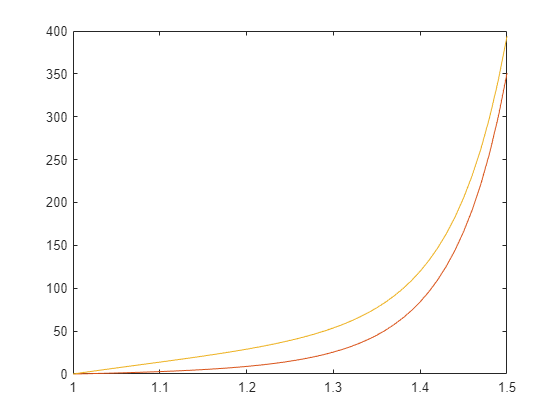


I1 = eval(trace(C));
I4 = eval(lambda_f.^2);

T_11 = subs(T(1,1));
T_12 = subs(T(1,2));
T_22 = subs(T(2,2));

figure
plot(lambda1,T_11,lambda1,T_12,lambda1,T_22)

## #2